% mode='open/'
% fileFolder=fullfile(['receive/', mode]);
% dirOutput=dir(fullfile(fileFolder,'*.txt'));
% fileNames={dirOutput.name};
% 
% file_name=fileNames{1}
% file=['receive/' , mode, file_name];
% data= importdata(file);
% llap(data, file_name, mode);
modes ={'beijing/'} 

modes = 1×1 cell 数组
    {'beijing/'}


mode = 'beijing/'

file = 'receive/beijing/20211207171243.txt'

time = 115200

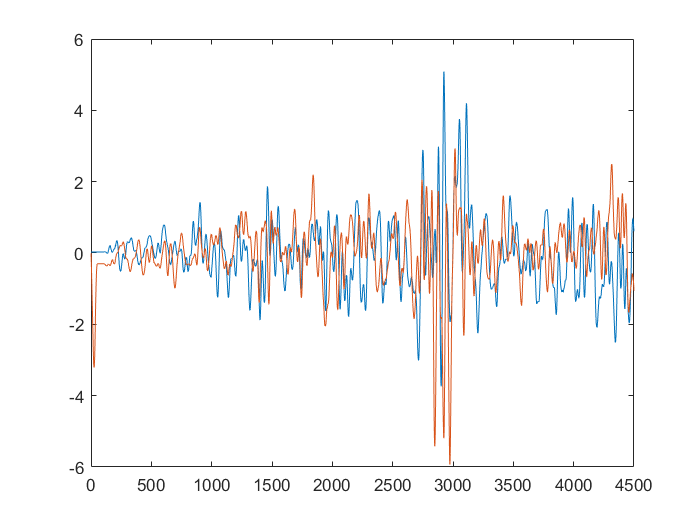

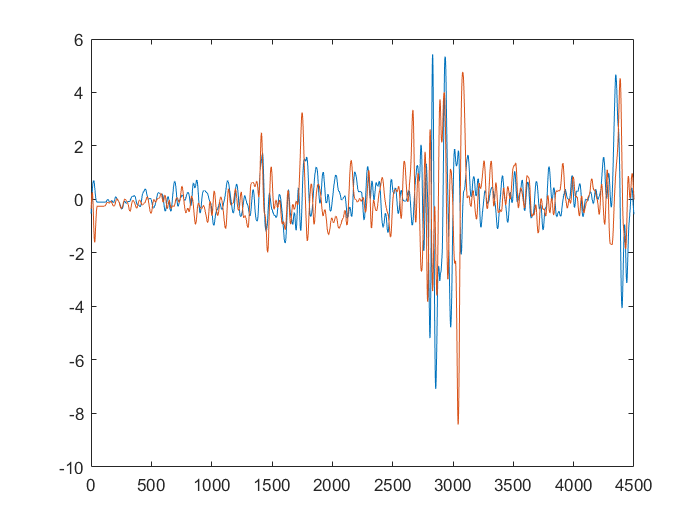

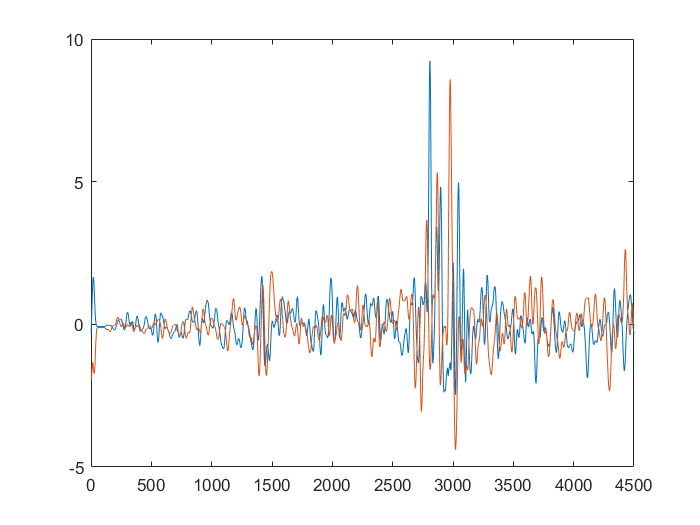

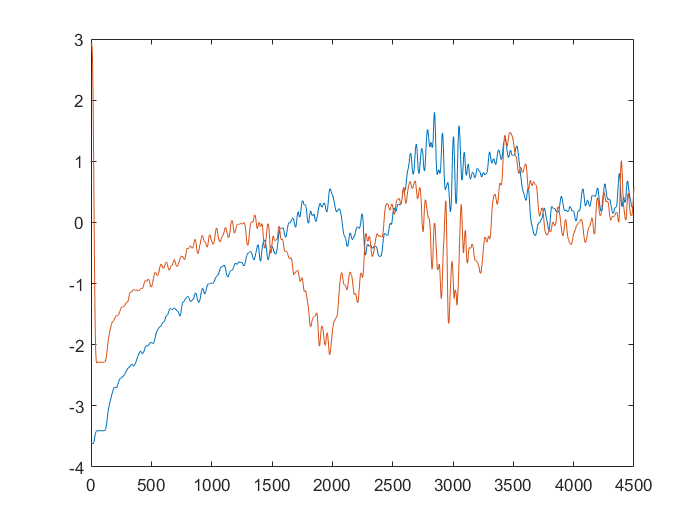

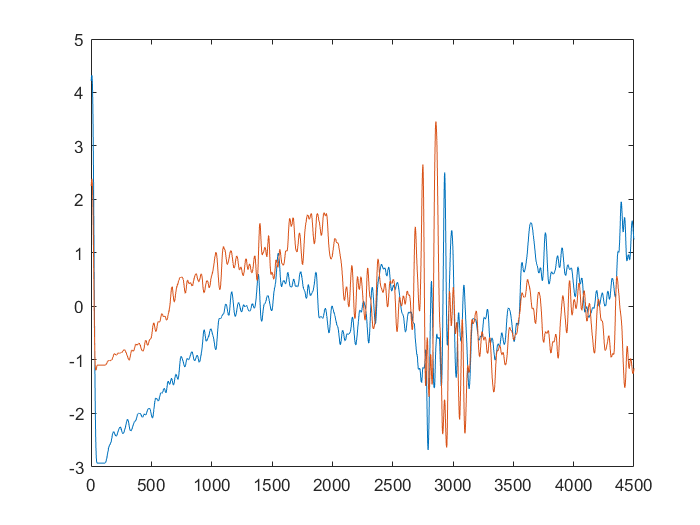

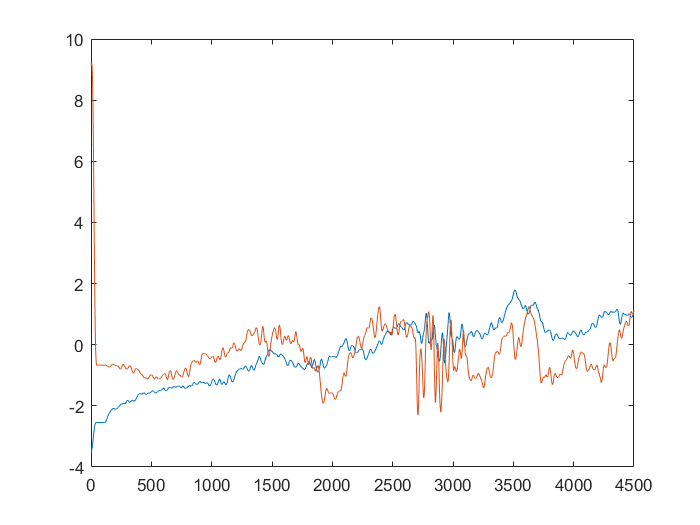

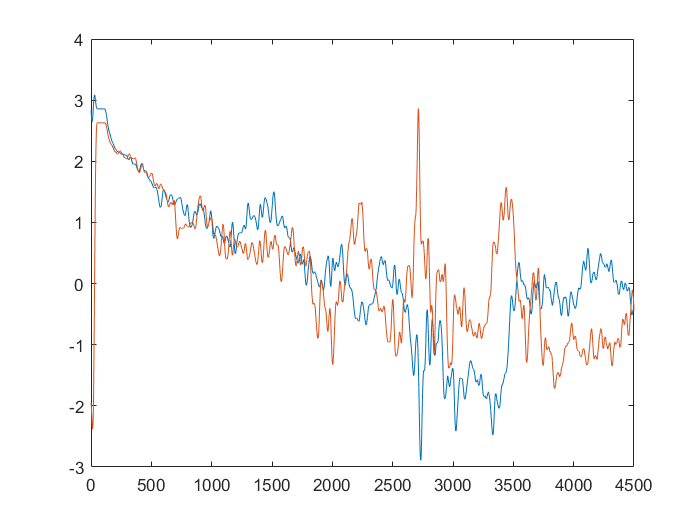

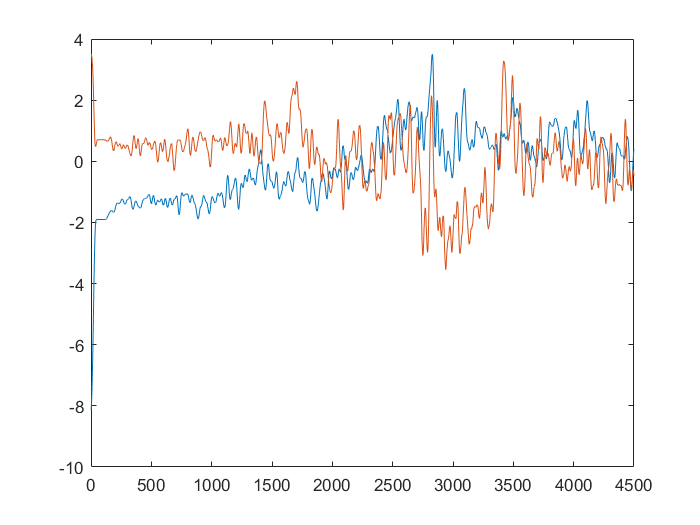

file = 'receive/beijing/20211207171551.txt'

time = 122880

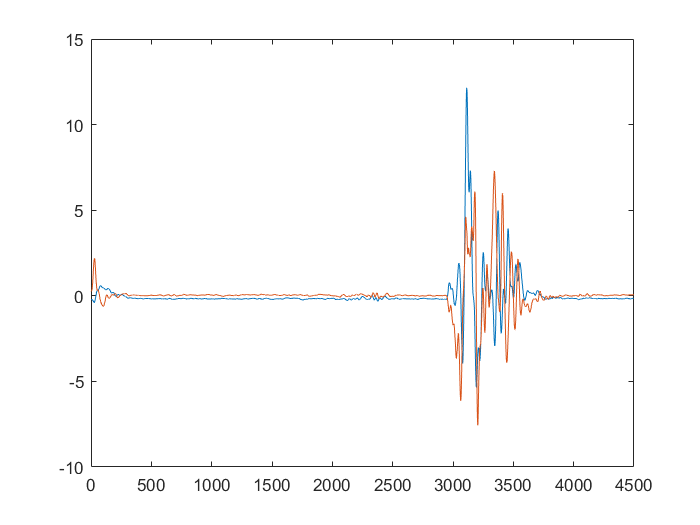

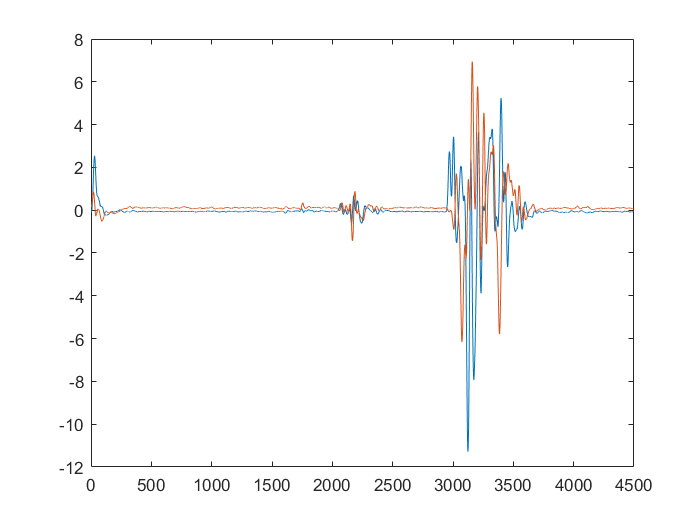

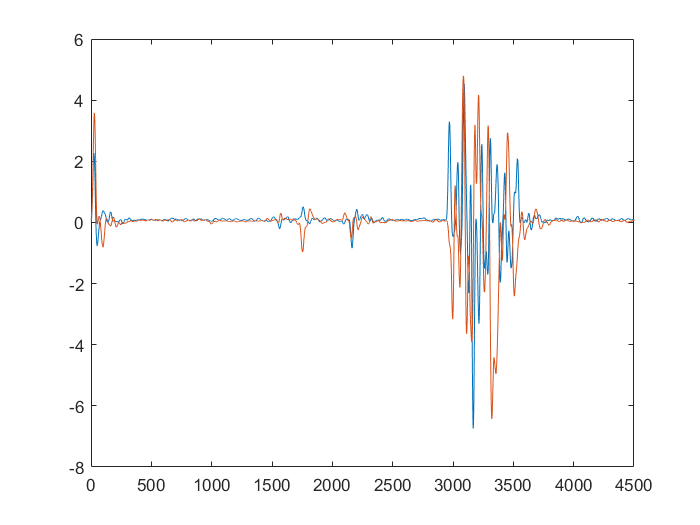

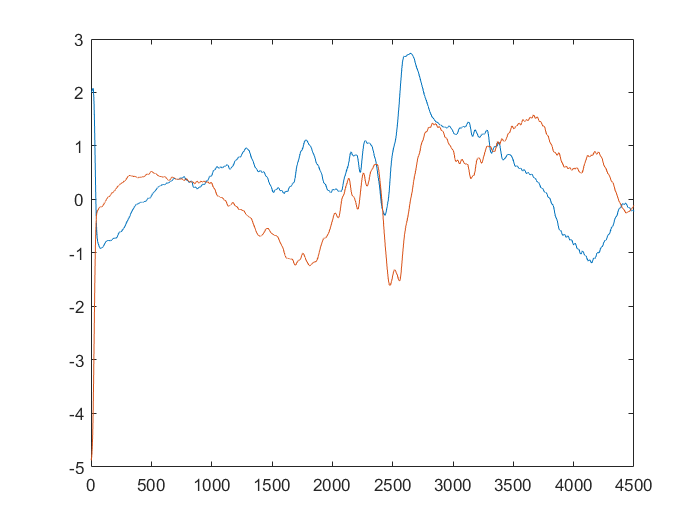

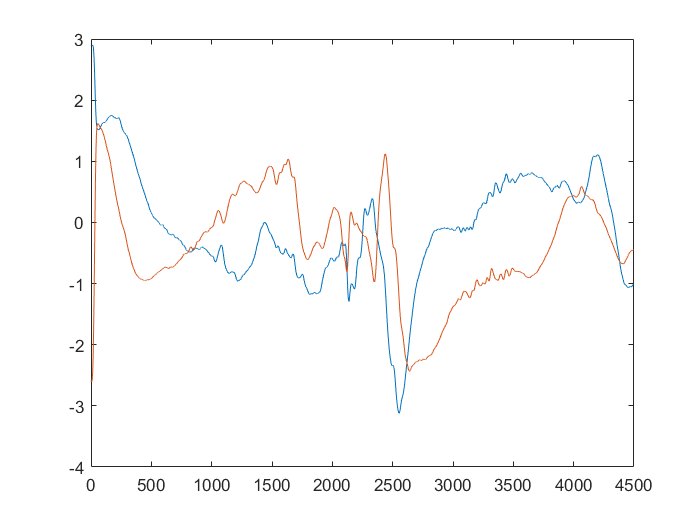

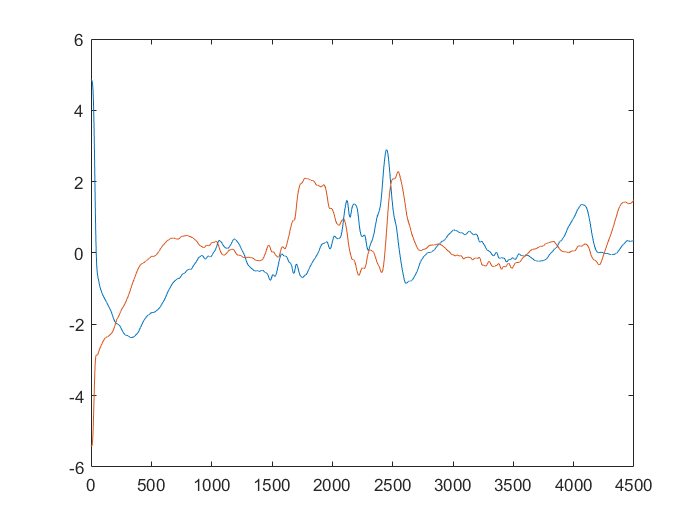

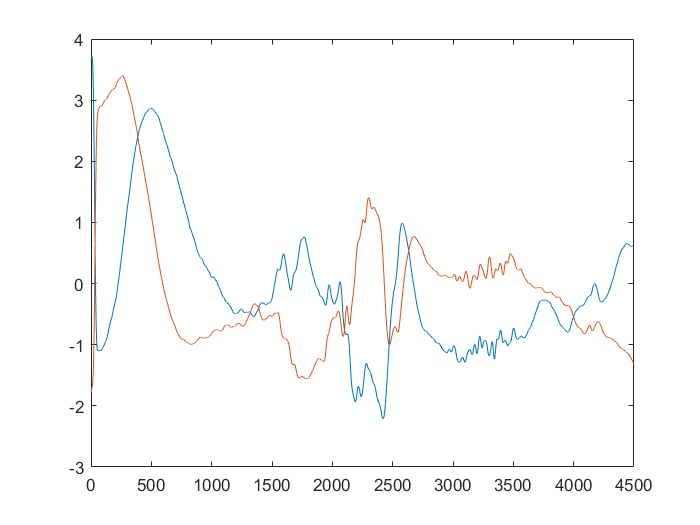

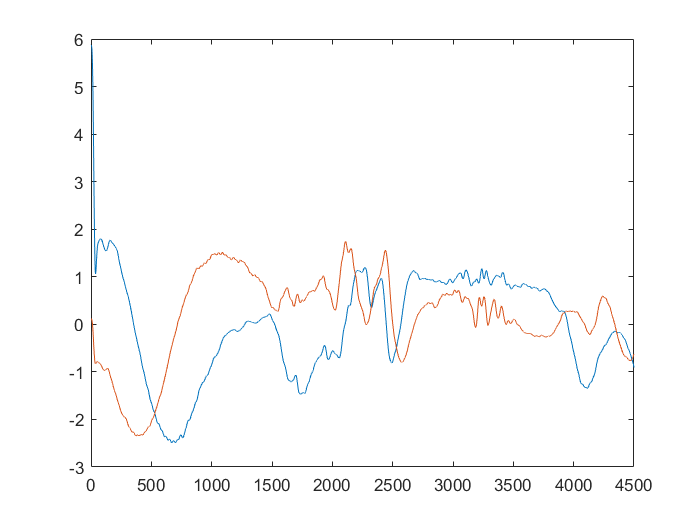

file = 'receive/beijing/20211207171636.txt'

time = 215040

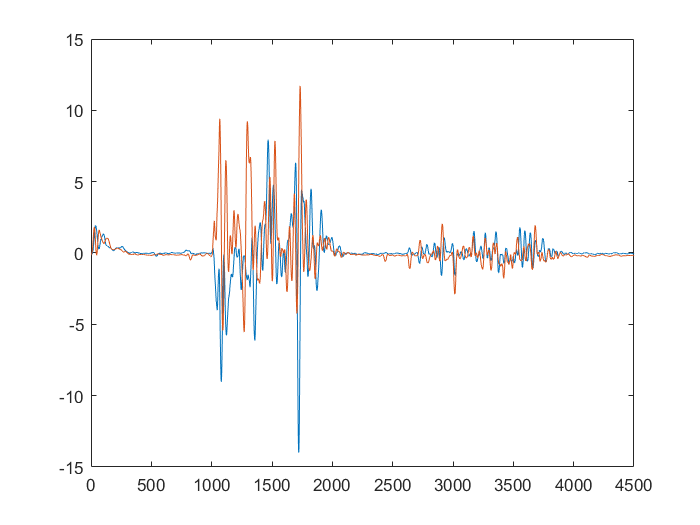

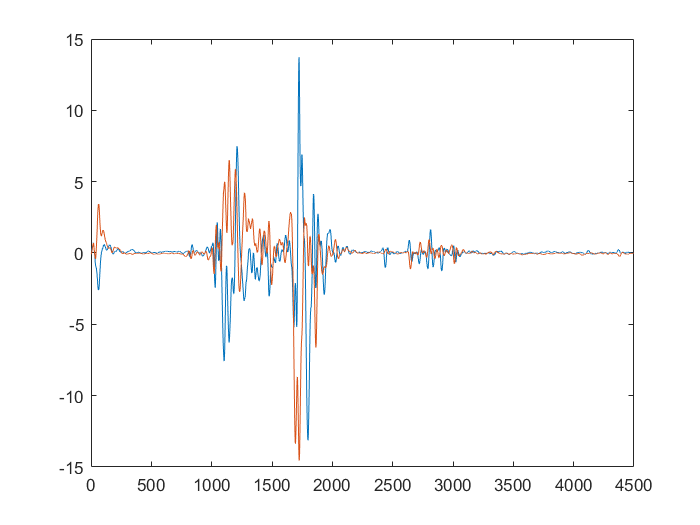

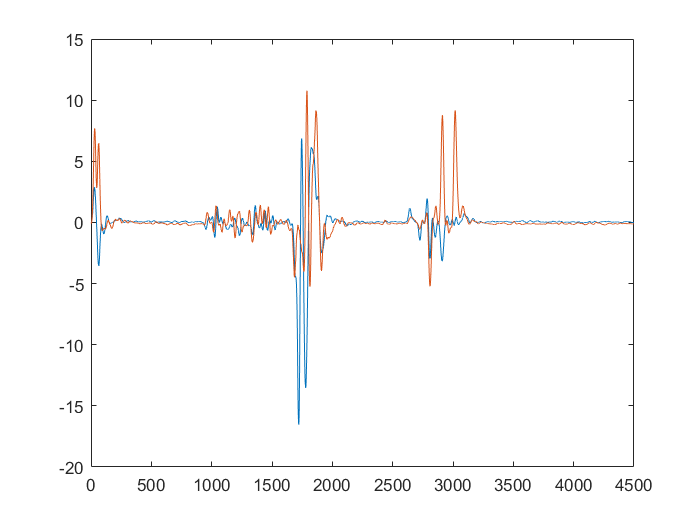

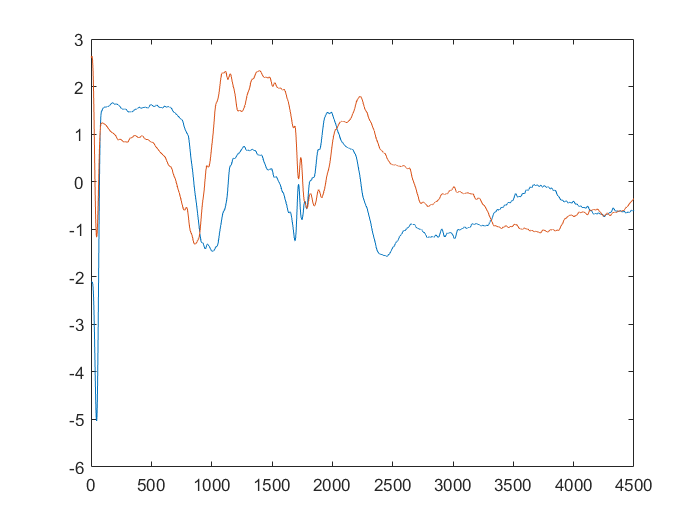

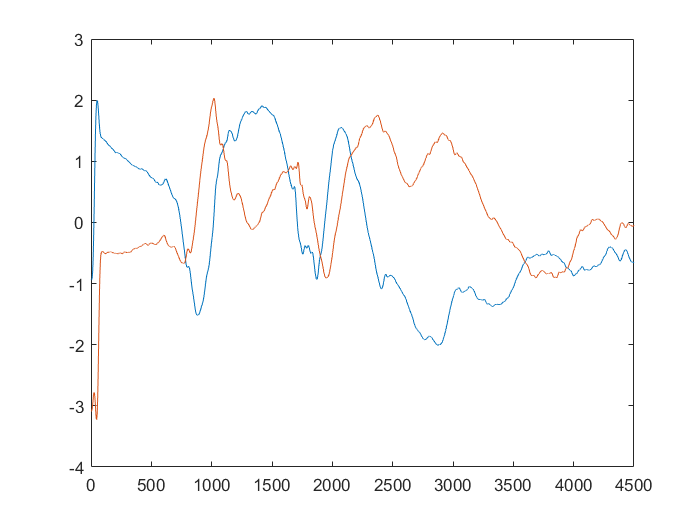

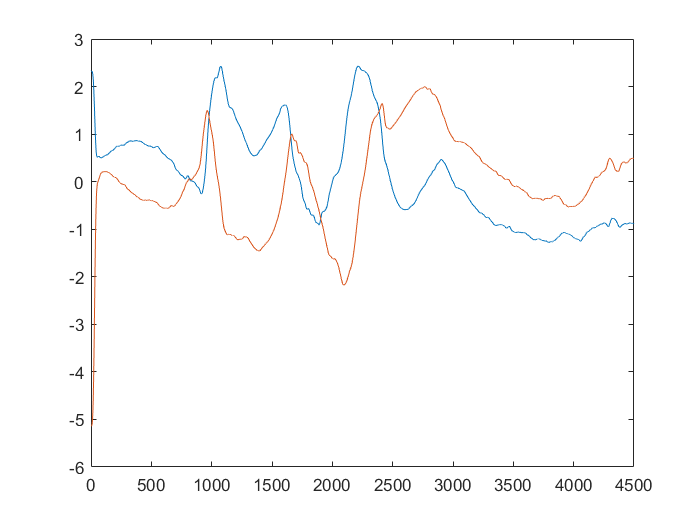

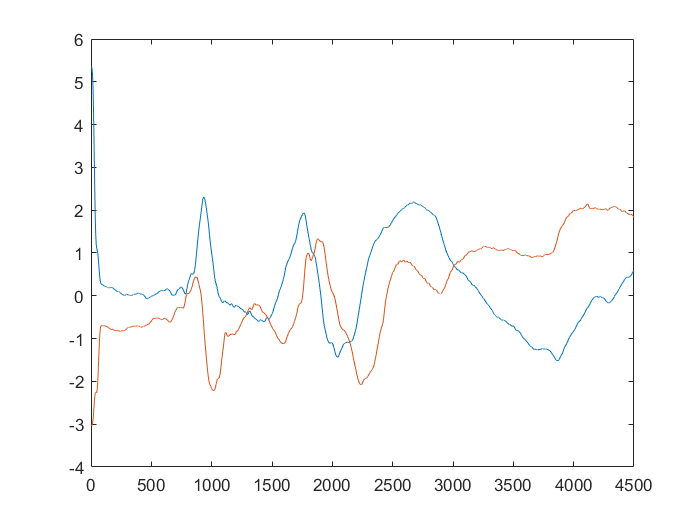

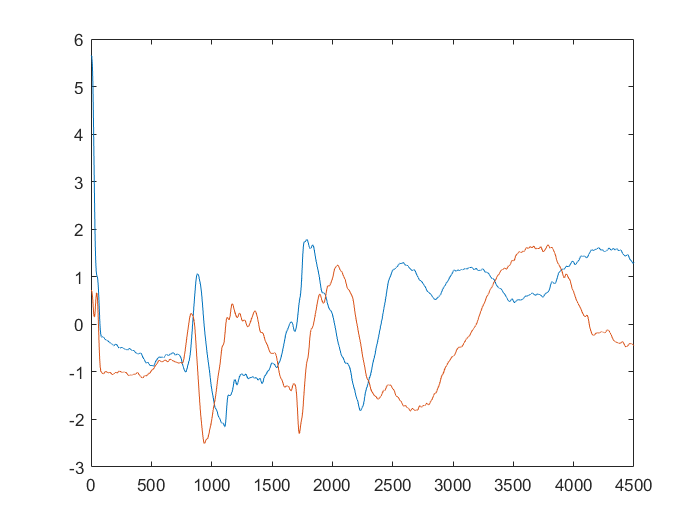

% modes ={'open/', 'close/', 'click/', 'flip/', 'push/'} 
for m = modes
    mode = m{1}
    fileFolder=fullfile(['receive/', mode]);
    dirOutput=dir(fullfile(fileFolder,'*.txt'));
    fileNames={dirOutput.name};
    for i =1:length(fileNames)
        
        file=['receive/', mode, fileNames{i}]
        data= importdata(file);
        llap(data, fileNames{i}, mode);
    end
end

function [data, file_name, mode] = llap(data, file_name, mode)
fs = 48000;
f = [];
f0 = 17250;


time=length(data)
for i=1:8
    f = [f f0+(i-1)*750];
end

t = 0:1/fs:(time-1)/fs;
I = [];
Q = [];

% raw fre
for i=1:8
    I = [I; cos(2*pi*f(i)*t)];
    Q = [Q; cos(2*pi*f(i)*t+pi/2)];
end

% IQ
I1=data .* I';
Q1=data .* Q';


% cic
cic=dsp.CICDecimator(16,17,3);
I1_cic = [];
Q1_cic = [];
for i=1:8
    I1_cic =[I1_cic; cic(I1(:, i))'];
    Q1_cic =[Q1_cic; cic(Q1(:, i))'];
end 


I1_cic=normalize(I1_cic, 2);
Q1_cic=normalize(Q1_cic, 2);

% padding
if size(I1_cic, 2)>4500
    I1_cic=I1_cic(:, 1:4500);
else
    I1_cic = padarray(I1_cic, [0 (4500-size(I1_cic, 2))/2]);
end

if size(Q1_cic, 2)>4500
    Q1_cic=Q1_cic(:, 1:4500);
else
    Q1_cic = padarray(Q1_cic, [0 (4500-size(Q1_cic, 2))/2]);
end

for i =1:8
    figure;
    plot(I1_cic(i, :));
    hold on;
    plot(Q1_cic(i, :));
end



% obtain IQ
fig = strsplit(file_name, '.');
IQ = [I1_cic; Q1_cic];
dlmwrite( ['IQ/', mode, fig{1}, '.txt'], IQ)



end